# Exercise 1

IM= imread('baboon.jpg');
IM= rgb2gray(IM);

tic
for x=1:100
    im_out = add_frame(IM);
end
toc

Elapsed time is 0.022694 seconds.


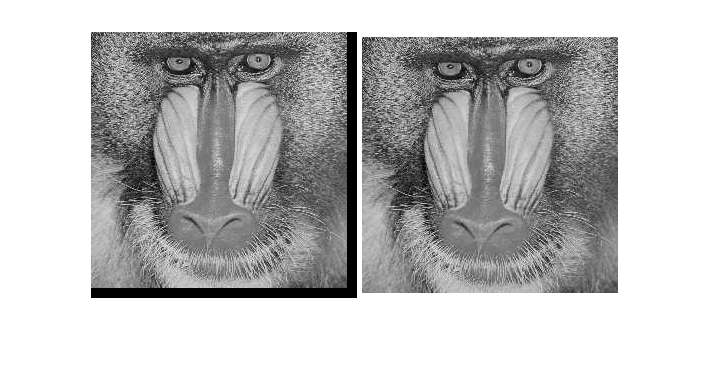


imshowpair(IM,im_out,'montage');


tic
for x=1:100
im_out_loops=add_frame_loops(IM);
end
toc

Elapsed time is 11.509895 seconds.


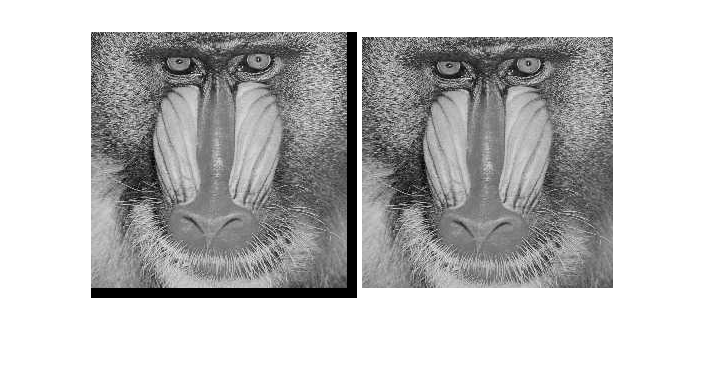


imshowpair(IM,im_out_loops,'montage');

function [im_out] = add_frame(im_in)
% adds a frame to an existing grayscale image
% im_in: original grayscale image
% im_out: black frame of 5 wide is added to im_in
[r,c]=size(im_in);
im_out=uint8(255*ones(r+10,c+10));
im_out(6:r+5,6:c+5)=im_in;
end

function [im_out] = add_frame_loops(im_in)
% adds a frame to an existing grayscale image
% im_in: original grayscale image
% im_out: black frame of 5 wide is added to im_in
[r,c]=size(im_in);
im_out=uint8(255*ones(r+10,c+10));

for i=6:r
    for j=6:c
        im_out(i,j)=im_in(i-4,j-4);
    end
end

end


% When running the script several times the tictoc time changes, but the
% one with the loops is always slower.

% If we run the function multiple times we have an exacter result, a sort
% of mean of multiple times the function

%If you want a black frame i.s.o. a white you change the background ones()
%to zeros()